# Track Generator

we input both x and y coordinates, the scripts then saves a interpolated and smoothed versioned of the provided path in a .mat file.

n_points = 50

n_points = 50

%function [spl_dots, spline_points, tck, u] = gen_path(dim)
points = rand(20, 2)*100 - 50;

% Perform Convex Hull
k = convhull(points(:, 1), points(:, 2));

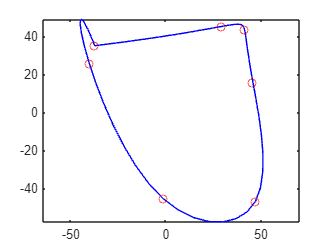

x = linspace(0,2*pi,length(k)); 
y = [points(k,1), points(k,2)];
pp = spline(x,y');
yy = ppval(pp, linspace(0,2*pi,n_points));
plot(yy(1,:),yy(2,:),'-b',y(:,1),y(:, 2),'or')
axis equal

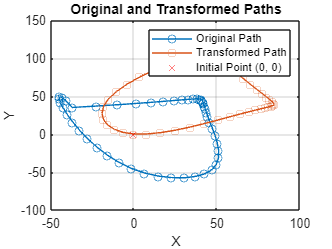

transformedPath = transformPath(yy');

% Display the original and transformed paths
figure;
plot(yy(1, :), yy(2, :), 'o-', 'DisplayName', 'Original Path');
hold on;
plot(transformedPath(:, 1), transformedPath(:, 2), 's-', 'DisplayName', 'Transformed Path');
plot(0, 0, 'rx', 'DisplayName', 'Initial Point (0, 0)');
legend;
grid on;
xlabel('X');
ylabel('Y');
title('Original and Transformed Paths');
hold off

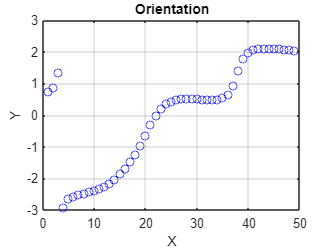

% Calculate the orientation reference for each point
orientationReference = atan2(transformedPath(2:end, 2) - transformedPath(1:end-1, 2), transformedPath(2:end, 1) - transformedPath(1:end-1, 1));

plot(1:length(orientationReference), orientationReference,"bo")
title("Orientation")
xlabel("X")
ylabel("Y")
grid on

function transformedPath = transformPath(inputPath)
    % Randomly select the initial point
    initialPointIndex = randi(size(inputPath, 1));
    initialPoint = inputPath(initialPointIndex, :);

    % Translate all points to align the initial point to (0, 0)
    translatedPath = inputPath - initialPoint;

    % Rotate all points to align the second point with y-coordinate equal to 0
    angle = atan2(translatedPath(initialPointIndex + 1, 2), translatedPath(initialPointIndex + 1, 1));
    rotationMatrix = [cos(-angle), -sin(-angle); sin(-angle), cos(-angle)];
    rotatedPath = (rotationMatrix * translatedPath')';

    % Output the transformed path
    transformedPath = rotatedPath;
end